clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
% DHparameter=[0 0 0.04 0;
%              0.12 pi/2 0 13*pi/30;
%              0.194 0 0 -23*pi/30;
%              0 -pi/2 0.176 0;
%              0 pi/2 0 pi/2;
%              0 pi/2 0 0]

% DHparameter=[0 0 4 0;
%              12 pi/2 0 0;
%              19.4 0 0 0;
%              0 -pi/2 17.6 0;
%              0 pi/2 0 0;
%              0 pi/2 0 0]
DHparameter=[0 pi/2 0.04 0;
             0.12 0 0 13*pi/30+pi/2;
             0.194 -pi/2 0 -23*pi/30+pi/2;
             0 0 0.176 0;
             0 pi/2 0 pi/2;
             0 0 0 0]

DHparameter =          0    1.5708    0.0400         0
    0.1200         0         0    2.9322
    0.1940   -1.5708         0   -0.8378
         0         0    0.1760         0
         0    1.5708         0    1.5708
         0         0         0         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",6,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
% joint1.PositionLimits = [-pi/3 pi/3];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
joint2.HomePosition = 13*pi/30+pi/2;
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];
body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [0 0.1];
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [0 0.1];
body6.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------


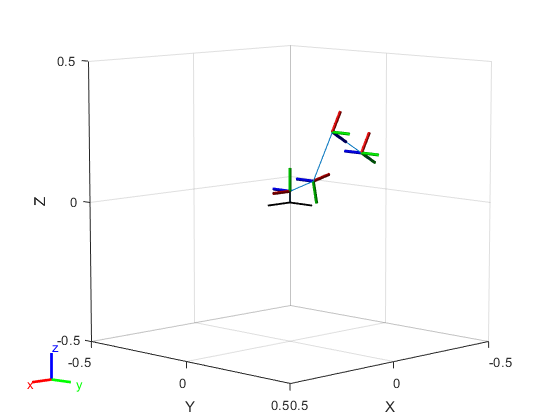


show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

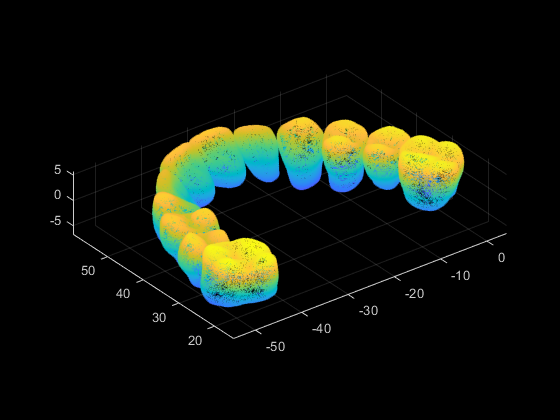

% Read and plot complete denture
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

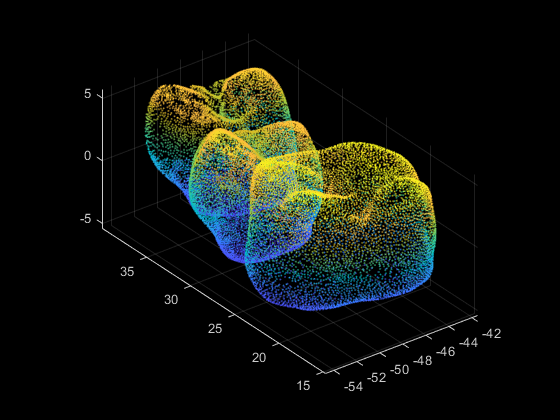


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

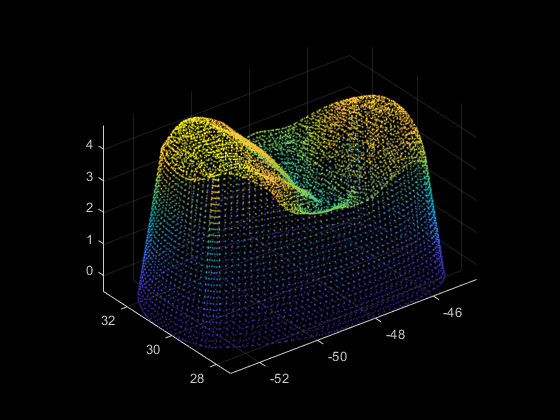


% Import and plot final model individually
stlData_fin = stlread("1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

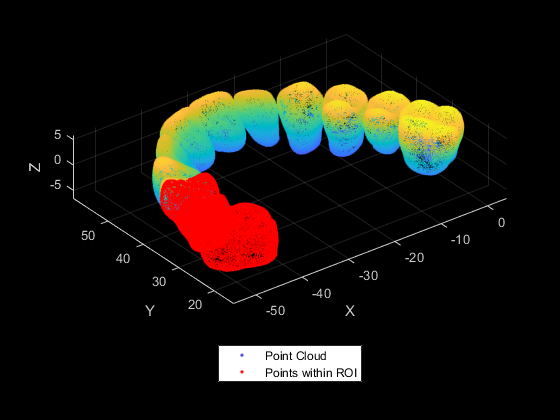


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

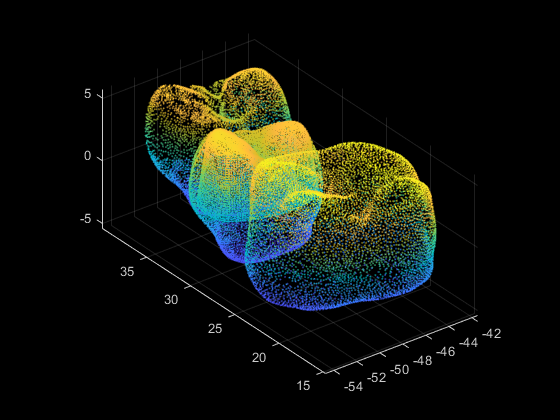


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

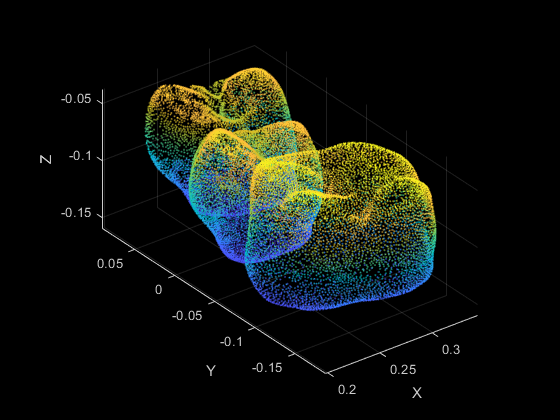


%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.8 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

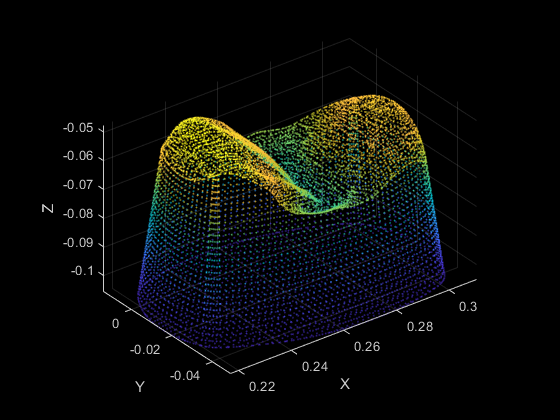

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.005

r = 0.0050

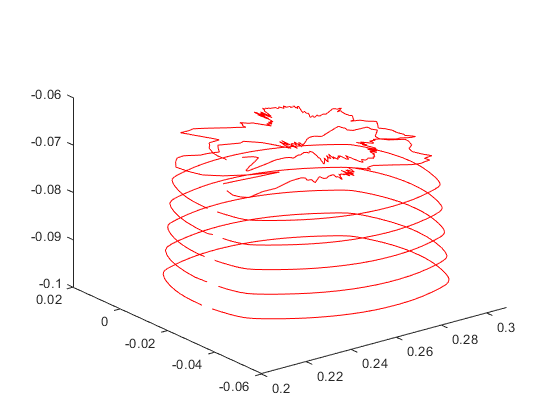

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],5);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

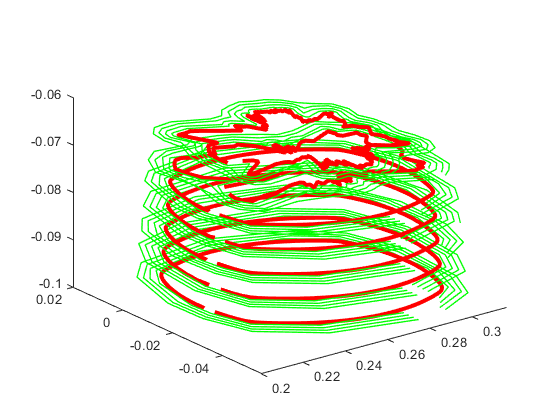

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,20);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {86×3 double}    {57×3 double}    {86×3 double}    {62×3 double}    {82×3 double}    {161×3 double}    {328×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {14×3 double}    {14×3 double}    { 67×3 double}    { 99×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {14×3 double}    {14×3 double}    { 50×3 double}    { 66×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {14×3 double}    {14×3 double}    { 41×3 double}    { 51×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {13×3 double}    {14×3 double}    { 35×3 double}    { 42×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

## `Save all quarters in arrays`

curve1 = allPoints{5,1}

curve1 =     0.2746   -0.0560   -0.0975
    0.2394   -0.0501   -0.0975
    0.2171   -0.0377   -0.0975
    0.2108   -0.0232   -0.0975
    0.2103   -0.0096   -0.0975
    0.2179    0.0094   -0.0975
    0.2286    0.0168   -0.0975
    0.2634    0.0200   -0.0975
    0.2954    0.0115   -0.0975
    0.3089    0.0025   -0.0975


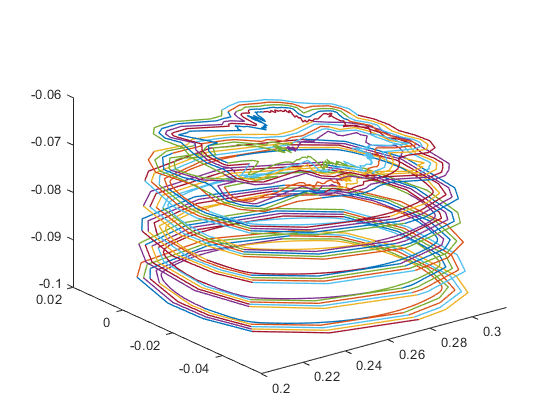

appendAllPoints = [];
figure

for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

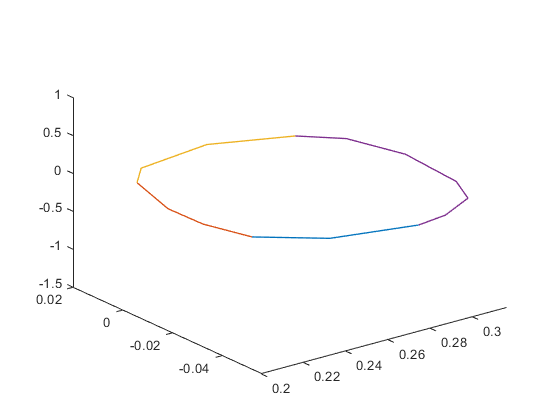

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back

## `Splitting Geometry and Forming into Trajectory`

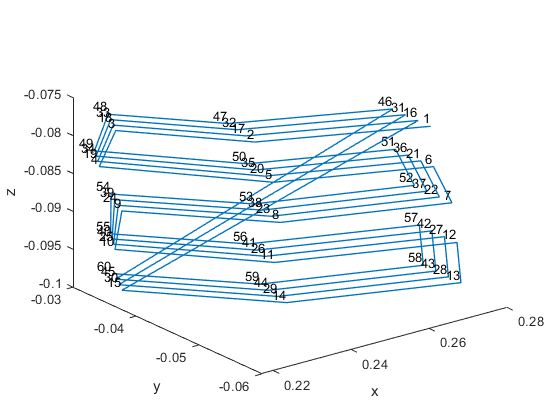

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);

q1_traj_arr_fixed = [];
for i = 1:60
    q1_traj_arr_fixed(i,:) = q1_traj_arr(i,:);
end

q2_traj_arr_fixed = [];
for i = 1:80
    q2_traj_arr_fixed(i,:) = q2_traj_arr(i,:);
end

q3_traj_arr_fixed = [];
for i = 1:80
    q3_traj_arr_fixed(i,:) = q3_traj_arr(i,:);
end

q4_traj_arr_fixed = [];
for i = 1:135
    q4_traj_arr_fixed(i,:) = q4_traj_arr(i,:);
end

save fixed_contour.mat q1_traj_arr_fixed q2_traj_arr_fixed q3_traj_arr_fixed q4_traj_arr_fixed

figure
plotQuarter(q1_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

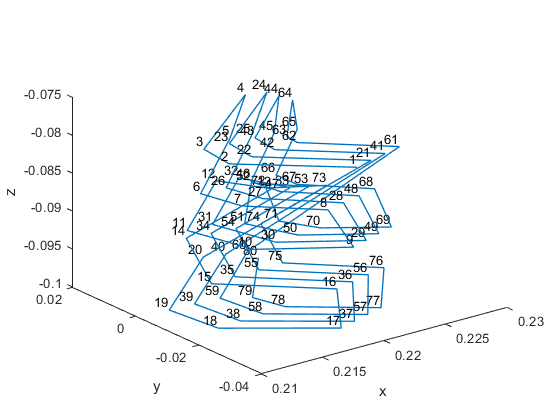

plotQuarter(q2_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

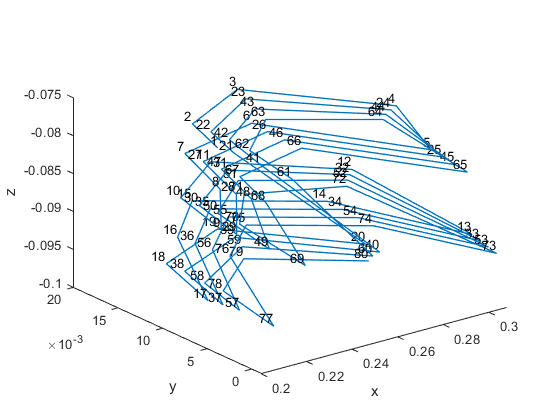

plotQuarter(q3_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

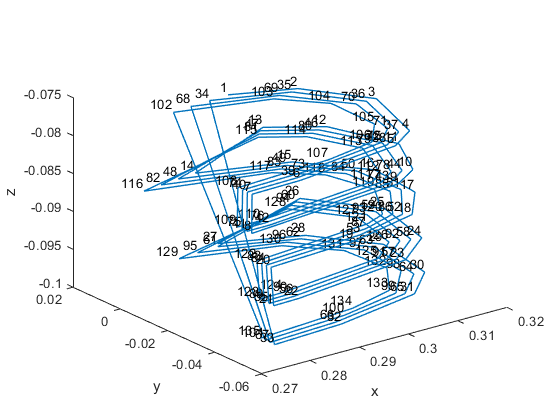

plotQuarter(q4_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
hold off

## `Calculate IK for Trajectories`

ik = inverseKinematics("RigidBodyTree",dental);
weights = [0 0 0 1 1 1];
q0 = homeConfiguration(dental);
qinitial = q0;
% ik.SolverParameters.MaxIterations = 45000;
% ik.SolverParameters.MaxTime = 1000
for i = 1:length(q1_traj_arr_fixed)
%     point = q1_traj_arr(i,:);
    pose = trvec2tform(q1_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q1_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end
% q1_traj_arr(5,:)
% getTransform(dental,q1_config(:,5),'Body6')

qinitial = q0;
for i = 1:length(q2_traj_arr_fixed)
    pose = trvec2tform(q2_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q2_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end
qinitial = q0;
for i = 1:length(q3_traj_arr_fixed)
    pose = trvec2tform(q3_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q3_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end
qinitial = q0;
for i = 1:length(q4_traj_arr_fixed)
    pose = trvec2tform(q4_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q4_config(:,i) = qsol;
    qinitial=qsol;
    solinfo;
end

save q_configs q1_config q2_config q3_config q4_config;
% q_config = matfile('q_configs.mat');
% q1_config = q_config.q1_config;
% q1_config = trapveltraj(q1_config,length(q1_config(1,:)),"EndTime",2);


%Combine and add home config between
homeConfig = findHomeConfig(ptCloud_fin);
pose = trvec2tform(homeConfig);
home = ik("Body6",pose,weights,dental.homeConfiguration);
%Need to get traj between last config of each q and home, then add these
%trajs to q_tot
t = 20;
q_1tohome = trapveltraj([q1_config(:,length(q1_config(1,:))),home],t,"EndTime",2);
q_hometo2 = trapveltraj([home,q2_config(:,1)],t,"EndTime",2);
q_2tohome = trapveltraj([q2_config(:,length(q2_config(1,:))),home],t,"EndTime",2)

q_2tohome =     0.0124    0.0148    0.0222    0.0344    0.0514    0.0734    0.1002    0.1308    0.1617    0.1926    0.2235    0.2544    0.2853    0.3159    0.3427    0.3647    0.3817    0.3939    0.4013    0.4037
    0.7971    0.8118    0.8556    0.9287    1.0309    1.1625    1.3232    1.5066    1.6917    1.8768    2.0619    2.2470    2.4321    2.6156    2.7763    2.9078    3.0101    3.0831    3.1270    3.1416
   -2.5550   -2.5442   -2.5117   -2.4576   -2.3819   -2.2846   -2.1656   -2.0298   -1.8927   -1.7557   -1.6187   -1.4817   -1.3447   -1.2089   -1.0899   -0.9925   -0.9168   -0.8627   -0.8303   -0.8195
   -2.4038   -2.3889   -2.3439   -2.2690   -2.1641   -2.0293   -1.8645   -1.6764   -1.4866   -1.2968   -1.1070   -0.9173   -0.7275   -0.5394   -0.3746   -0.2397   -0.1348   -0.0599   -0.0150    0.0000
   -1.2775   -1.2696   -1.2457   -1.2059   -1.1501   -1.0785   -0.9909   -0.8909   -0.7900   -0.6892   -0.5883   -0.4875   -0.3866   -0.2866   -0.1991   -0.1274   -0.0717   -0.0318   -

q_hometo3 = trapveltraj([home,q3_config(:,1)],t,"EndTime",2);
q_3tohome = trapveltraj([q3_config(:,length(q3_config(1,:))),home],t,"EndTime",2);
q_hometo4 = trapveltraj([home,q4_config(:,1)],t,"EndTime",2);


% q_tot = [q1_config ];
q_tot = [q1_config q2_config q3_config q4_config];

## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
robotCollision = isInCollision(q_tot, MSH, dental);
if ~robotCollision
    disp("The robot is in not in collision.")
else
    disp("The robot is in collision")
end

The robot is in not in collision.


## `Calculate and Plot Closest points`

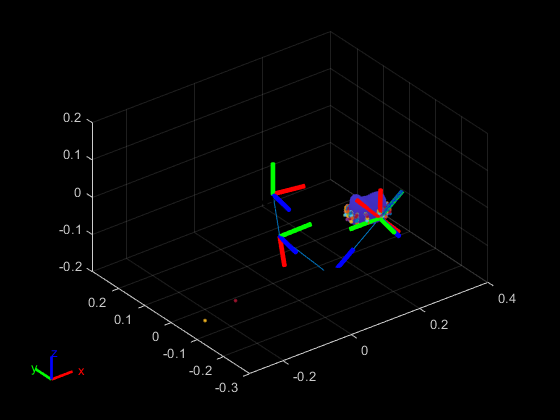

[minimum,ind,ee_arr] = min2pts(dental,q_tot,ptCloud_fin);

figure
pcshow(ptCloud_fin)
hold on
show(dental,home,'PreservePlot',false);
hold on
% plotQuarter(q1_traj_arr); hold on
% plotQuarter(q2_traj_arr); hold on
% plotQuarter(q3_traj_arr); hold on
% plotQuarter(q4_traj_arr); hold on
plotClosest(dental,q_tot,ee_arr,ind,ptCloud_fin);

% plotClosest(dental,q2_config,ee_arr,ind,ptCloud_fin);
% plotClosest(dental,q3_config,ee_arr,ind,ptCloud_fin);


## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
%     curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body6','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 20;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis([-0.3 0.4 -0.3 0.3 -0.2 0.2])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
%         line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
        plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
    
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = -0.04;
    homeConfig = [x y z];
end

### `Check if path in collision or not`

function isTrajectoryInCollision = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
    rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
end